%%               - Autonomous USV Obstacle Avoidance Algorithm -               %%
%            This code uses an algorithm based on the Tangent Method            %
%                to find a collision free path around an obstacle               %
%                                                                               %
%                Written by Dimitrios Stergianelis on August 2018, YH 2020-08-26%
%                                                                               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
% Clean the workspace and close the open figures
clear
clc
close all
tic;

%% Parameters - Setting up the problem

% Start point S (XS, YS)
% XS = -1;
% YS = 7;
XS = 15;
YS = 30;
 
% Target point T (XT, YT)
% XT = 12;
% YT = 15;
XT = 30;
YT = 45;
 
% Obstacle representation: circle with centre at (XO, YO) and radius RO
% XO = 5;
% YO = 10;
% RO = 3;
XO = 23;
YO = 36;
RO = 4.429;
 
% Safety radius RB
% Was set equal to the radius of the vessel region (RV), for the simulations
RB = 0.571;
 
%% Core calculations
 
% Position vectors, to be used for plotting
X_pos = XS;
Y_pos = YS;
 
% Find the straight-line equation (Y = a*X+b) connecting the initial and
% target points
a = (YS - YT)/(XS - XT);
b = (XS*YT - XT*YS)/(XS - XT);
 
% Find the determinant radius RD
RD = RO + RB;
 
% Plot the centre of the circle
plot(XO, YO, '.b')
hold on
axis equal; box on;
xlabel('X (m)'); ylabel('Y (m)');
 
% Plot the circle (X-XO)^2+(Y-YO)^2=RD^2 with XO, YO and RD red --- line
plot_circle(XO, YO, RD, 'r');
 
% Plot the circle (X-XO)^2+(Y-YO)^2=RO^2 with XO, YO and RO blue --- line
plot_circle(XO, YO, RO, 'b');
 
% Add description (text) to data points
txt1 = ' Start point';
text(XS,YS,txt1,'VerticalAlignment','top')
 
txt2 = ' Target point';
text(XT,YT,txt2,'VerticalAlignment','top')
 
% Check if the vessel is already inside obstacle region
if (sqrt((XS - XO)^2 + (YS - YO)^2) < RD) || (sqrt((XT - XO)^2 + (YT - YO)^2) < RD)
    error('Start/Target point(s) inside obstacle region')
end
 
% Calculate the length of the straight line from S to T
L = sqrt((XT - XS)^2 + (YT - YS)^2);
disp(['Straight-line length: ' num2str(L)])

Straight-line length: 21.2132


 
% Find the intersection point(s) between the line and the circle (equation: (X-XO)^2+(Y-YO)^2 = RD^2)
% Need to solve: (a^2 + 1)*X^2 + 2*(a*b - a*YO - XO)*X + (YO^2 - RD^2 + XO^2 - 2*b*YO + b^2) = 0
% Substitutions in the quadratic equation
A = (a^2 + 1);
B = 2*(a*b - a*YO - XO);
C = (YO^2 - RD^2 + XO^2 - 2*b*YO + b^2);
 
% Determinant calculation
D = B^2 - 4*A*C;
 
%% Finding the relative position between the straight line and the obstacle
 
% Check if the straight line intersects with the obstacle
if ((XS == XT) && ((XS <= XO - RD) || (XS >= XO + RD)))
    % Route parallel to Y-axis and no intersection point
    % Continue moving on the straight line
    NoIntersection = true;
    disp('No Intersection')
    
elseif ((YS == YT) && ((YS <= YO - RD) || (YS >= YO + RD)))
    % Route parallel to X-axis and no intersection point
    % Continue moving on the straight line
    NoIntersection = true;
    disp('No Intersection')
    
elseif (D <= 0) % Check determinant value
    % 0 or 1 solutions, i.e. none or one intersection point
    % Continue moving on the straight line
    NoIntersection = true;
    disp('No Intersection')
    
else % Two solutions (intersection points), with coordinates (X1, Y1) & (X2, Y2)
    if (XS == XT) % Route parallel to Y-axis
        X1 = XS;
        X2 = XS;
        Y1 = YO - sqrt (RD^2 - (XS-XO)^2);
        Y2 = YO + sqrt (RD^2 - (XS-XO)^2);
        
    elseif (YS == YT) % Route parallel to X-axis
        X1 = XO - sqrt (RD^2 - (YS-YO)^2);
        X2 = XO + sqrt (RD^2 - (YS-YO)^2);
        Y1 = YS;
        Y2 = YS;
        
    else % Route with random orientation
        X1 = (-B + sqrt(B^2 - 4*A*C))/(2*A);
        X2 = (-B - sqrt(B^2 - 4*A*C))/(2*A);
        Y1 = a*X1 + b;
        Y2 = a*X2 + b;
    end
    
    % Plot the intersection points
    plot(X1, Y1, 'xk')
    plot(X2, Y2, 'xk')
    
    % Check if the intersection points belong to the line segment from S to T
    if (XT > XS)
        if (XS < X1 && X2 < XT)
            NoIntersection = false;
            disp('Intersection')
        else
            NoIntersection = true;
            disp('No Intersection')
        end
        
    elseif (XT == XS)
        if (YT > YS)
            if (YS < Y1 && Y2 < YT)
                NoIntersection = false;
                disp('Intersection')
            else
                NoIntersection = true;
                disp('No Intersection')
            end
        else % YT < YS
            if (YT < Y1 && Y2 < YS)
                NoIntersection = false;
                disp('Intersection')
            else
                NoIntersection = true;
                disp('No Intersection')
            end
        end
        
    else % XT < XS
        if (XT < X1 && X2 < XS)
            NoIntersection = false;
            disp('Intersection')
        else
            NoIntersection = true;
            disp('No Intersection')
        end
    end
end

Intersection


 
%% Way of updating position vector
 
if (NoIntersection)
    % Continue moving on the straight line
    % Update position vector
    X_pos = [X_pos XT];
    Y_pos = [Y_pos YT];
    
else % Determine the direction to turn
    % Finding the tangent lines and tangential points
    % Solve Y = a1*X + b1 and (X - XO)^2 + (Y - YO)^2 = RD^2 and require the
    % determinant equal to zero in order to have one contact point
    % syms X XO YO RD a1 b1
    % eqn = (X - XO)^2 + (a1*X + b1 - YO)^2 == RD^2;
    % solx = solve(eqn, X)
    % X1 = (XO + YO*a1 - a1*b1 + (RD^2*a1^2 + RD^2 - XO^2*a1^2 + 2*XO*YO*a1 - 2*XO*a1*b1 - YO^2 + 2*YO*b1 - b1^2)^(1/2))/(a1^2 + 1)
    % X2 = (XO + YO*a1 - a1*b1 - (RD^2*a1^2 + RD^2 - XO^2*a1^2 + 2*XO*YO*a1 - 2*XO*a1*b1 - YO^2 + 2*YO*b1 - b1^2)^(1/2))/(a1^2 + 1)
    
    % b1 = (YS - a1*XS)
    % syms X XO YO RD a1 YS XS
    % eqn = RD^2*a1^2 + RD^2 - XO^2*a1^2 + 2*XO*YO*a1 - 2*XO*a1*(YS - a1*XS) - YO^2 + 2*YO*(YS - a1*XS) - (YS - a1*XS)^2 == 0;
    % solx = solve(eqn, a1)
    
    % These are the straight-lines starting from S and been tangential to the obstacle
    a11 = (XO*YS - XO*YO + XS*YO - XS*YS + RD*(- RD^2 + XO^2 - 2*XO*XS + XS^2 + YO^2 - 2*YO*YS + YS^2)^(1/2))/(RD^2 - XO^2 + 2*XO*XS - XS^2);
    a12 = -(XO*YO - XO*YS - XS*YO + XS*YS + RD*(- RD^2 + XO^2 - 2*XO*XS + XS^2 + YO^2 - 2*YO*YS + YS^2)^(1/2))/(RD^2 - XO^2 + 2*XO*XS - XS^2);
    b11 = (YS - a11*XS);
    b12 = (YS - a12*XS);
    
    % Equation (Y = a11v*X + b11v) for the line vertical to the first
    % tangential line (Y = a11*X + b11)
    a11v = -1/a11;
    b11v = YO - a11v*XO;
    
    % Finding the cross point C11 (XC11, YC11) of two lines (Y = a11v*X + b11v and Y = a11*X + b11) = the point where the tangent line
    % meet the circle
    XC11 = (b11v - b11)/(a11 - a11v);
    YC11 = a11*XC11 + b11;
    
    % Equation (Y = a12v*X + b12v) for the line vertical to the first
    % tangential line (Y = a12*X + b12)
    a12v = -1/a12;
    b12v = YO - a12v*XO;
    
    % Finding the cross point C12 (XC12, YC12) of two lines (Y = a12v*X + b12v and Y = a12*X + b12) = the point where the tangent line
    % meet the circle
    XC12 = (b12v - b12)/(a12 - a12v);
    YC12 = a12*XC12 + b12;
    
    % Plot tangential points C11 and C12
    plot(XC11, YC11, 'ob')
    plot(XC12, YC12, 'ok')
    
    % This are the straight-lines starting from T and been tangential to the circle
    a21 = (XO*YT - XO*YO + XT*YO - XT*YT + RD*(- RD^2 + XO^2 - 2*XO*XT + XT^2 + YO^2 - 2*YO*YT + YT^2)^(1/2))/(RD^2 - XO^2 + 2*XO*XT - XT^2);
    a22 = -(XO*YO - XO*YT - XT*YO + XT*YT + RD*(- RD^2 + XO^2 - 2*XO*XT + XT^2 + YO^2 - 2*YO*YT + YT^2)^(1/2))/(RD^2 - XO^2 + 2*XO*XT - XT^2);
    b21 = (YT - a21*XT);
    b22 = (YT - a22*XT);
    
    % Equation (Y = a21v*X + b21v) for the line vertical to the first
    % tangential line (Y = a21*X + b21)
    a21v = -1/a21;
    b21v = YO - a21v*XO;
    
    % Finding the cross point C21 (XC21, YC21) of two lines (Y = a21v*X + b21v and Y = a21*X + b21) = the point where the tangent line
    % meet the circle
    XC21 = (b21v - b21)/(a21 - a21v);
    YC21 = a21*XC21 + b21;
    
    % Equation (Y = a22v*X + b22v) for the line vertical to the first
    % tangential line (Y = a22*X + b22)
    a22v = -1/a22;
    b22v = YO - a22v*XO;
    
    % Finding the cross point C22 (XC22, YC22) of two lines (Y = a22v*X + b22v and Y = a22*X + b22) = the point where the tangent line
    % meet the circle
    XC22 = (b22v - b22)/(a22 - a22v);
    YC22 = a22*XC22 + b22;
    
    % Plot tangential points C21 and C22
    plot(XC21, YC21, 'ok')
    plot(XC22, YC22, 'ob')
    
    if (XS == XT) % Extra criterion because in this case YCRIT=YO and cannot determine the direction to turn
        if (XS >= XO)
            if (YS > YO) % First quadrant
                CCW = true;
                disp('First quadrant')
            else % YS < YO Fourth quadrant
                CCW = false;
                disp('Fourth quadrant')
            end
        else % XS < XO
            if (YS > YO) % Second quadrant
                CCW = false;
                disp('Second quadrant')
            else % YS < YO Third quadrant
                CCW = true;
                disp('Third quadrant')
            end
        end
        XC = XS;
        YC = YO;
        
    else % XS not equal with XT
        if (YS == YT)
            YCRIT = YS;
            XC = XO;
            YC = YS;
        else % Calculate the YCRIT
            YCRIT = a*XO + b;
            % Find the line equation (Y = av*X + bv) which is lateral to the
            % initial one (S to T) and is crossing from the centre of the obstacle
            av = -1/a;
            bv = (a*YO + XO)/a;
            % Find the cross point of the two lines (XC, YC)
            % Solve the system (Y = a*X + b) and (Y = av*X + bv)
            XC = (bv - b)/(a - av);
            YC = a*XC + b;
        end
        
        % If YCRIT>=YO then turn CCW angle f1 and CW f2
        if (YCRIT >= YO)
            CCW = true;
        else % If YCRIT<YO then turn CW angle f1 and CCW f2
            CCW = false;
        end
    end
    
    % %Plot the cross point
    % plot(XC,YC,'+m')
    
    % Calculate the distance from the centre of the obstacle (XO, YO) to the
    % cross point (XC, YC)
    LR = sqrt((XC - XO)^2 + (YC - YO)^2);
    
    % Calculate the distance from the cross point to the circumference
    LM = RD - LR;
    
    if (((CCW == true) && (XT<XS)) || ((CCW == false) && (XT>=XS))) % turn CW and use C11 & C22
        
        % Find the line equation (Y = as*X + bs) between S to C11
        as = a11;
        bs = b11;
        
        % Find the line equation (Y = at*X + bt) between T to C22
        at = a22;
        bt = b22;
        
        if (XT == XS)
            if (XS < XO)
                % Find the cross point (XC1, YC1) between (X = XS - LM) and (Y = as*X + bs)
                XC1 = XS - LM;
                YC1 = as*XC1 + bs;
                % Find the cross point (XC2, YC2) between (X = XS - LM) and (Y = at*X + bt)
                XC2 = XS - LM;
                YC2 = at*XC2 + bt;
                
            else % XS >= XO
                % Find the cross point (XC1, YC1) between (X = XS + LM) and (Y = as*X + bs)
                XC1 = XS + LM;
                YC1 = as*XC1 + bs;
                % Find the cross point (XC2, YC2) between (X = XS + LM) and (Y = at*X + bt)
                XC2 = XS + LM;
                YC2 = at*XC2 + bt;
            end
        else
            % Find the line equation (Y = a*X + bp) which is parallel to the (Y = a*X+b) and is tangential to the circle
            if (XT > XS)
                bp = b - LM/cos(atan(a));
            else
                bp = b + LM/cos(atan(a));
            end
            
            % Another way to find bp is by solving the system (Y = a*X + bp) and (Y = av*X+bv) for (X,Y) and demand X,Y to be valid for the equation (X-XO)^2+(Y-YO)^2=RD^2
            % syms bv bp a av XO YO RD
            % eqn = ((bv - bp)/(a - av) - XO)^2 + (av*(bv - bp)/(a - av) + bv - YO)^2 == RD^2;
            % solx = solve(eqn, bp)
            % bp1 = (bv - XO*a + XO*av + a*(RD^2*av^2 + RD^2 - XO^2*av^2 + 2*XO*YO*av - 2*XO*av*bv - YO^2 + 2*YO*bv - bv^2)^(1/2) - av*(RD^2*av^2 + RD^2 - XO^2*av^2 + 2*XO*YO*av - 2*XO*av*bv - YO^2 + 2*YO*bv - bv^2)^(1/2) + YO*av^2 - YO*a*av + a*av*bv)/(av^2 + 1)
            % bp2 = (bv - XO*a + XO*av - a*(RD^2*av^2 + RD^2 - XO^2*av^2 + 2*XO*YO*av - 2*XO*av*bv - YO^2 + 2*YO*bv - bv^2)^(1/2) + av*(RD^2*av^2 + RD^2 - XO^2*av^2 + 2*XO*YO*av - 2*XO*av*bv - YO^2 + 2*YO*bv - bv^2)^(1/2) + YO*av^2 - YO*a*av + a*av*bv)/(av^2 + 1)
            
            % Find the cross point (XC1, YC1) between (Y = a*X + bp) and (Y = as*X + bs)
            XC1 = (bp - bs)/(as - a);
            YC1 = as*XC1 + bs;
            
            % Find the cross point (XC2, YC2) between (Y = a*X + bp) and (Y = at*X + bt)
            XC2 = (bp - bt)/(at - a);
            YC2 = at*XC2 + bt;
        end
    else % (((YCRIT>YO) && (XT>XS)) || ((YCRIT<YO) && (XT<XS))) turn CCW and use C12 & C21
        % Find the line equation (Y = as*X + bs) between S to C12
        as = a12;
        bs = b12;
        
        % Find the line equation (Y = at*X + bt) between T to C21
        at = a21;
        bt = b21;
        
        if (XT == XS)
            if (XS < XO)
                % Find the cross point (XC1, YC1) between (X = XS - LM) and (Y = as*X + bs)
                XC1 = XS - LM;
                YC1 = as*XC1 + bs;
                % Find the cross point (XC2, YC2) between (X = XS - LM) and (Y = at*X + bt)
                XC2 = XS - LM;
                YC2 = at*XC2 + bt;
                
            else % XS >= XO
                % Find the cross point (XC1, YC1) between (X = XS + LM) and (Y = as*X + bs)
                XC1 = XS + LM;
                YC1 = as*XC1 + bs;
                
                % Find the cross point (XC2, YC2) between (X = XS + LM) and (Y = at*X + bt)
                XC2 = XS + LM;
                YC2 = at*XC2 + bt;
            end
        else
            if (XT > XS)
                bp = b + LM/cos(atan(a));
            else
                bp = b - LM/cos(atan(a));
            end
            
            % Find the cross point (XC1, YC1) between (Y = a*X + bp) and (Y = as*X + bs)
            XC1 = (bp - bs)/(as - a);
            YC1 = as*XC1 + bs;
            % Find the cross point (XC2, YC2) between (Y = a*X + bp) and (Y = at*X + bt)
            XC2 = (bp - bt)/(at - a);
            YC2 = at*XC2 + bt;
        end
    end
    
    % Plot some important points for debugging
    plot(XC1, YC1, 'xk')
    plot(XC2, YC2, 'xk')
    
    % Calculate the distance between the cross points
    LP = sqrt((XC1 - XC2)^2 + (YC1 - YC2)^2);
    
    % Calculate the distance between the S and the C1_ points
    L1 = sqrt((XS - XC1)^2 + (YS - YC1)^2);
    
    % Calculate the distance between the T and the C2_ points
    L2 = sqrt((XT - XC2)^2 + (YT - YC2)^2);
    
    % Calculate the first and second turn angle
    % If YCRIT>=YO then turn CCW angle f1 and CW f2
    if (CCW == true)
        f1 = asin(LM/L1);
        f2 = -asin(LM/L2);
    else % If YCRIT<YO then turn CW angle f1 and CCW f2
        f1 = -asin(LM/L1);
        f2 = asin(LM/L2);
    end
    
    %% Way of updating position vector
    
    % Update position vector when there is intersection
    if (XT > XS) % Forward motion
        % Update position vector - first part
        X_pos = [X_pos, (XS + L1*cos(atan(a) + f1))];
        Y_pos = [Y_pos, (YS + L1*sin(atan(a) + f1))];
        
        % Update position vector - second part
        X_pos = [X_pos, (XS + L1*cos(atan(a) + f1) + LP*cos(atan(a)))];
        Y_pos = [Y_pos, (YS + L1*sin(atan(a) + f1) + LP*sin(atan(a)))];
        
        % Update position vector - third part
        X_pos = [X_pos, (XS + L1*cos(atan(a) + f1) + LP*cos(atan(a)) + L2*cos(atan(a) + f2))];
        Y_pos = [Y_pos, (YS + L1*sin(atan(a) + f1) + LP*sin(atan(a)) + L2*sin(atan(a) + f2))];
        
    elseif (XS == XT) % Parallel to Y-axis motion
        % Update position vector - first part
        X_pos = [X_pos, (XS + sign(YS-YO)*L1*cos(pi/2 - f1))];
        Y_pos = [Y_pos, (YS - sign(YS-YO)*L1*sin(pi/2 - f1))];
        
        % Update position vector - second part
        X_pos = [X_pos, (XS + sign(YS-YO)*L1*cos(pi/2 - f1) - sign(YS - YO)*LP*cos(pi/2))];
        Y_pos = [Y_pos, (YS - sign(YS-YO)*L1*sin(pi/2 - f1) - sign(YS - YO)*LP*sin(pi/2))];
        
        % Update position vector - third part
        X_pos = [X_pos, (XS + sign(YS-YO)*L1*cos(pi/2 - f1) - sign(YS - YO)*LP*cos(pi/2) + sign(YS-YO)*L2*cos(pi/2 - f2))];
        Y_pos = [Y_pos, (YS - sign(YS-YO)*L1*sin(pi/2 - f1) - sign(YS - YO)*LP*sin(pi/2) - sign(YS-YO)*L2*sin(pi/2 - f2))];
        
    else % Backward motion
        % Update position vector - first part
        X_pos = [X_pos, (XS - L1*cos(atan(a) - f1))];
        Y_pos = [Y_pos, (YS - L1*sin(atan(a) - f1))];
        
        % Update position vector - second part
        X_pos = [X_pos, (XS - L1*cos(atan(a) - f1) - LP*cos(atan(a)))];
        Y_pos = [Y_pos, (YS - L1*sin(atan(a) - f1) - LP*sin(atan(a)))];
        
        % Update position vector - third part
        X_pos = [X_pos, (XS - L1*cos(atan(a) - f1) - LP*cos(atan(a)) - L2*cos(atan(a) - f2))];
        Y_pos = [Y_pos, (YS - L1*sin(atan(a) - f1) - LP*sin(atan(a)) - L2*sin(atan(a) - f2))];
    end
    
    % Calculate the total distance
    L_travel = L1 + LP + L2;
    disp(['Trajectory length: ' num2str(L_travel)])
    
    % Calculate the extra distance
    L_extra = L_travel - L;
    disp(['Extra distance travelled due to obstacle: ' num2str(L_extra)])
    
end

Trajectory length: 22.5023


Extra distance travelled due to obstacle: 1.2891


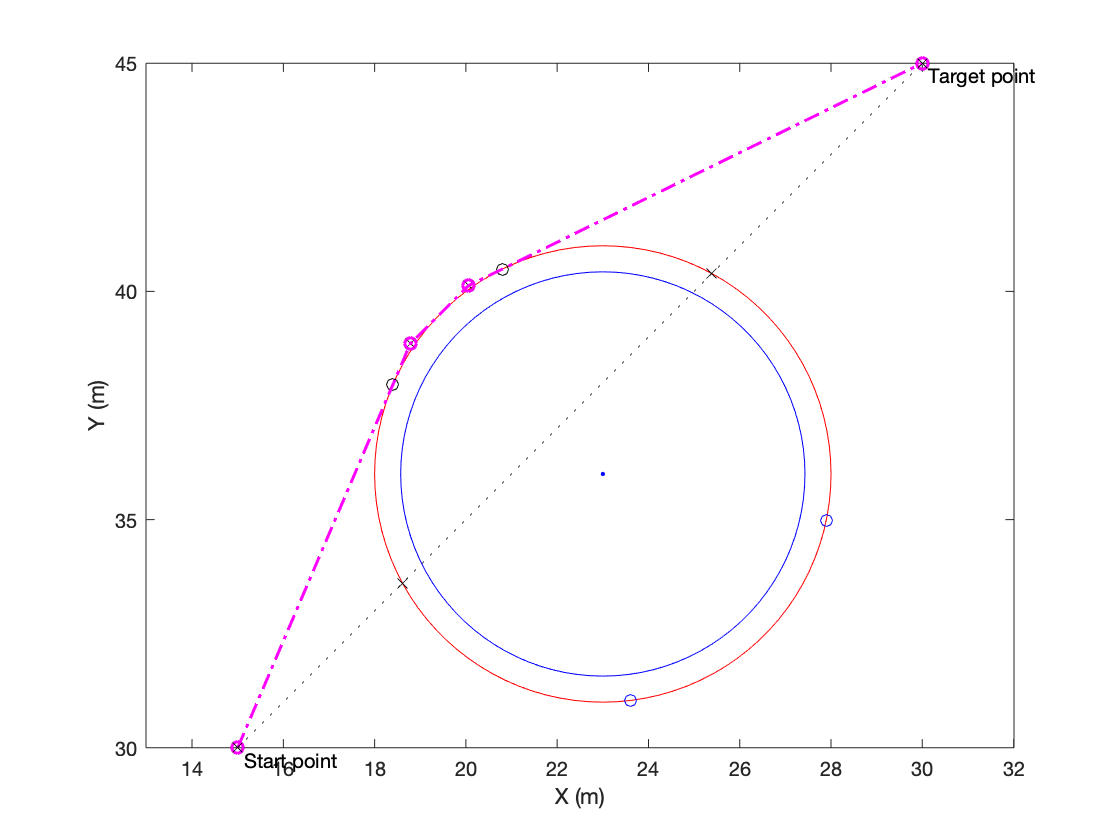

 
% Plot trajectory with magenta dash-dot line
plot(X_pos, Y_pos, '-.om', 'LineWidth', 1.5)
 
% Plot line Y=a*X+b with black dotted line
x = [XS, XT];
y = [YS, YT];
plot (x, y, ':xk')


toc

Elapsed time is 0.211599 seconds.
